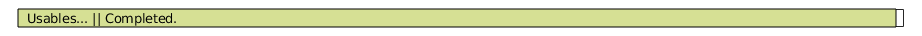

sm = SessManager;
%d = sm.cons_usable(SessManager.special_sessions_usable_index_single('Mouse2022'));
[coeffs, coeffs_pvals] = deal(zeros(sm.num_usable, 2));
progressbar('Usables...');
for s_i = 1:sm.num_usable
    d = sm.cons_usable(s_i);
    [T, td] = DecodeTensor.cut_tensor(d.data_tensor, d.tr_dir, [], []);
    [X, my_ks] = DecodeTensor.tensor2dataset(T, td);
    bw = d.opt.bin_width;
    n_reps = 16;
    [ps, ks] = deal(zeros(n_reps, numel(my_ks)));
    parfor i = 1:n_reps
        [~, ~, ps(i,:), ks(i,:)] = DecodeTensor.decode_tensor(T, td, bw, my_algs('ecoclin'), false, [], []);
    end
    
    insta_act = sqrt(sum(X.^2,2));
    insta_efn = sum(X.^2,2).^2 ./ sum(X.^4,2);
    insta_err = mean(abs(ps - ks)*bw,1).';
    %figure;
    %scatter(insta_efn, insta_err, 4, '.');
    lm = fitlm([zscore(insta_act), zscore(insta_efn)], zscore(insta_err));
    coeffs(s_i,:) = lm.Coefficients.Estimate([2 3]);
    coeffs_pvals(s_i, :) = lm.Coefficients.pValue([2 3]);
    assert(isequal(ks(1,:).', my_ks));
    progressbar(s_i/sm.num_usable);
end

save insta_pss.mat coeffs coeffs_pvals

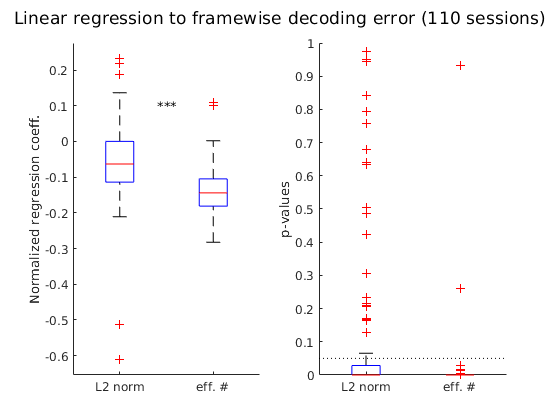

figure;
subplot(1,2,1);
boxplot(coeffs, {'L2 norm', 'eff. #'});
ylabel 'Normalized regression coeff.'
sr_pval = signrank(coeffs(:,1), coeffs(:,2));
text(1.5, 0.1, Utils.pstar(sr_pval), 'HorizontalAlign', 'center');
set(gca, 'Box', 'off');
subplot(1,2,2);
boxplot(coeffs_pvals, {'L2 norm', 'eff. #'});
l_ = refline(0, 0.05); l_.Color = 'k'; l_.LineStyle = ':';
ylabel 'p-values'
%set(gca, 'XAxisLocation', 'origin');
ylim([0 1]);
set(gca, 'Box', 'off');
sgtitle('Linear regression to framewise decoding error (110 sessions)');
Utils.printto('events_figs/f4_supplements', 'insta_efn.pdf');

org = Org; org.init;

mus = org.fetch('mus');
mus = cellfun(@cell2mat, mus, 'UniformOutput', false);
dmu_hd = cellfun(@(x) x(:,21:end) - x(:,1:20), mus, 'UniformOutput', false);
hd_efn = cellfun(@(x) sum(x.^2,1).^2 ./ sum(x.^4,1), dmu_hd, 'UniformOutput', false);
hd_efn_mean = cellfun(@mean, hd_efn);

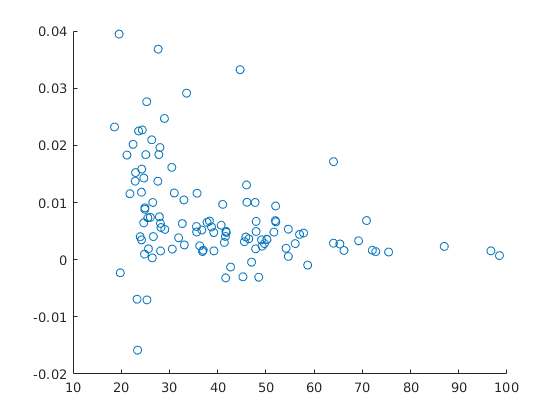

figure;
scatter(hd_efn_mean, asymp_snr./asymp_snr_shuf);

[rho, pval] = corr(hd_efn_mean.', asymp_snr./asymp_snr_shuf)

rho = -0.3406

pval = 2.7176e-04

fitlm(zscore(hd_efn_mean.'), zscore(asymp_snr./asymp_snr_shuf))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    4.2744e-17     0.09006    4.7461e-16             1
    x1               -0.34059    0.090472       -3.7646    0.00027176


Number of observations: 110, Error degrees of freedom: 108
Root Mean Squared Error: 0.945
R-squared: 0.116,  Adjusted R-Squared: 0.108
F-statistic vs. constant model: 14.2, p-value = 0.000272

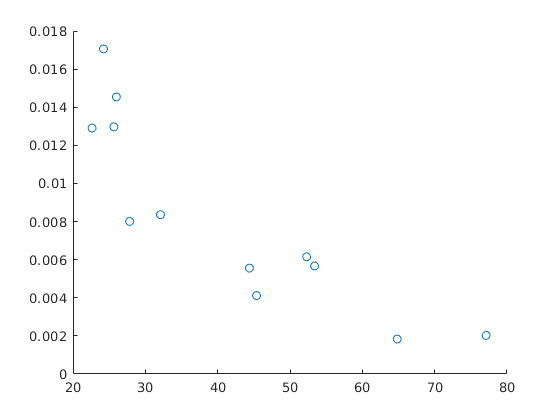

hd_efn_permouse = permouse(hd_efn_mean, org.mouse);
hd_asymp_ratio = permouse(asymp_snr./asymp_snr_shuf, org.mouse);

figure;
scatter(hd_efn_permouse, hd_asymp_ratio);

[rho, pval] = corr(hd_efn_permouse.', hd_asymp_ratio.')

rho = -0.8709

pval = 2.2610e-04

fitlm(zscore(hd_efn_permouse), zscore(hd_asymp_ratio))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   ___________    _______    __________    _________

    (Intercept)    -4.3085e-16    0.14877    -2.896e-15            1
    x1                -0.87095    0.15539        -5.605    0.0002261


Number of observations: 12, Error degrees of freedom: 10
Root Mean Squared Error: 0.515
R-squared: 0.759,  Adjusted R-Squared: 0.734
F-statistic vs. constant model: 31.4, p-value = 0.000226

function pm = permouse(x, mice)
sels = string(unique(mice)).' == string(mice);
pm = zeros(1,size(sels,1));
for i = 1:size(sels,1)
    pm(i) = mean(x(sels(i,:)));
end
end